# Predict Class Labels Using ClassificationTree Predict Block

This example shows how to train a classification decision tree model using the [Classification Learner](docid:stats_ug#buggk6h) app, and then use the [ClassificationTree Predict](docid:stats_ug#mw_d5dfffe4-12bb-4a68-ab65-00b4f321f2c5) block for label prediction in Simulink®. The block accepts an observation (predictor data) and returns the predicted class label and class score for the observation using the trained classification decision tree model. 

## Train Classification Model in Classification Learner App

Train a classification decision tree model by using hyperparameter optimization in the Classification Learner App.

1. In the MATLAB® Command Window, load the `ionosphere` data set, which contains radar return qualities (`Y`) and predictor data (`X`) of 34 variables. Radar returns are either of good quality (`'g'`) or bad quality (`'b'`). 

Load the `ionosphere` data set. Determine the sample size.

load ionosphere
n = numel(Y)

Suppose that the radar returns are detected in sequence, and you have the first 300 observations, but you have not received the last 51 yet. Partition the data into present and future samples.

prsntX = X(1:300,:);
prsntY = Y(1:300);
ftrX = X(301:end,:);
ftrY = Y(301:end);

2. Open Classification Learner. On the **Apps** tab, in the **Apps** section, click the **Show more** arrow to display the apps gallery. In the **Machine Learning and Deep Learning** group, click **Classification Learner**.

3. On the **Classification Learner** tab, in the **File** section, click **New Session** and select **From Workspace**.

4. In the New Session from Workspace dialog box, select the matrix `prsntX` from the **Data Set Variable** list. Under **Response**, click the **From workspace** option button and select the vector `prsntY` from the workspace. The default validation option is 5-fold cross-validation, to protect against overfitting. For this example, do not change the default settings.

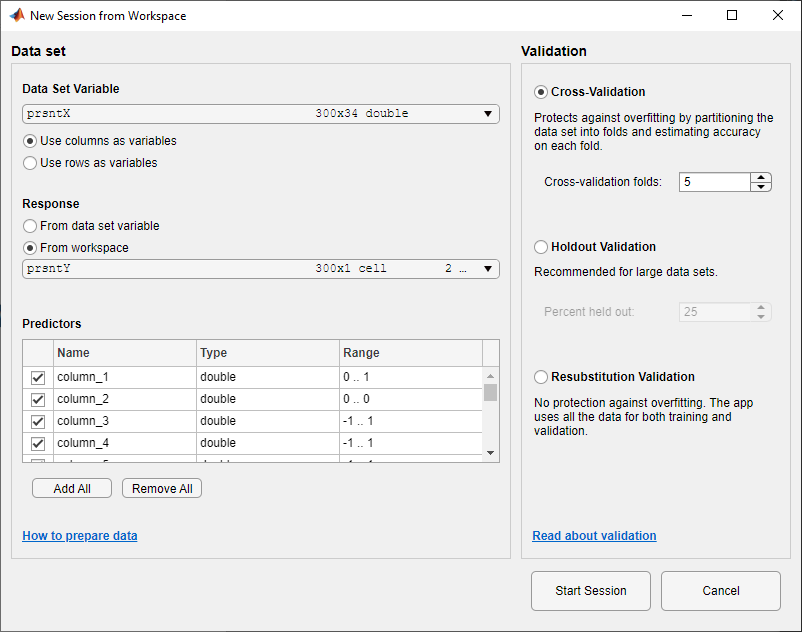

5. To accept the default options and continue, click **Start Session**.

6. Select an optimizable tree model to train. On the **Classification Learner** tab, in the **Model Type** section, click the **Show more** arrow to open the gallery. In the **Decision Trees** group, click **Optimizable Tree**. The app disables the **Use Parallel** button when you select an optimizable model.

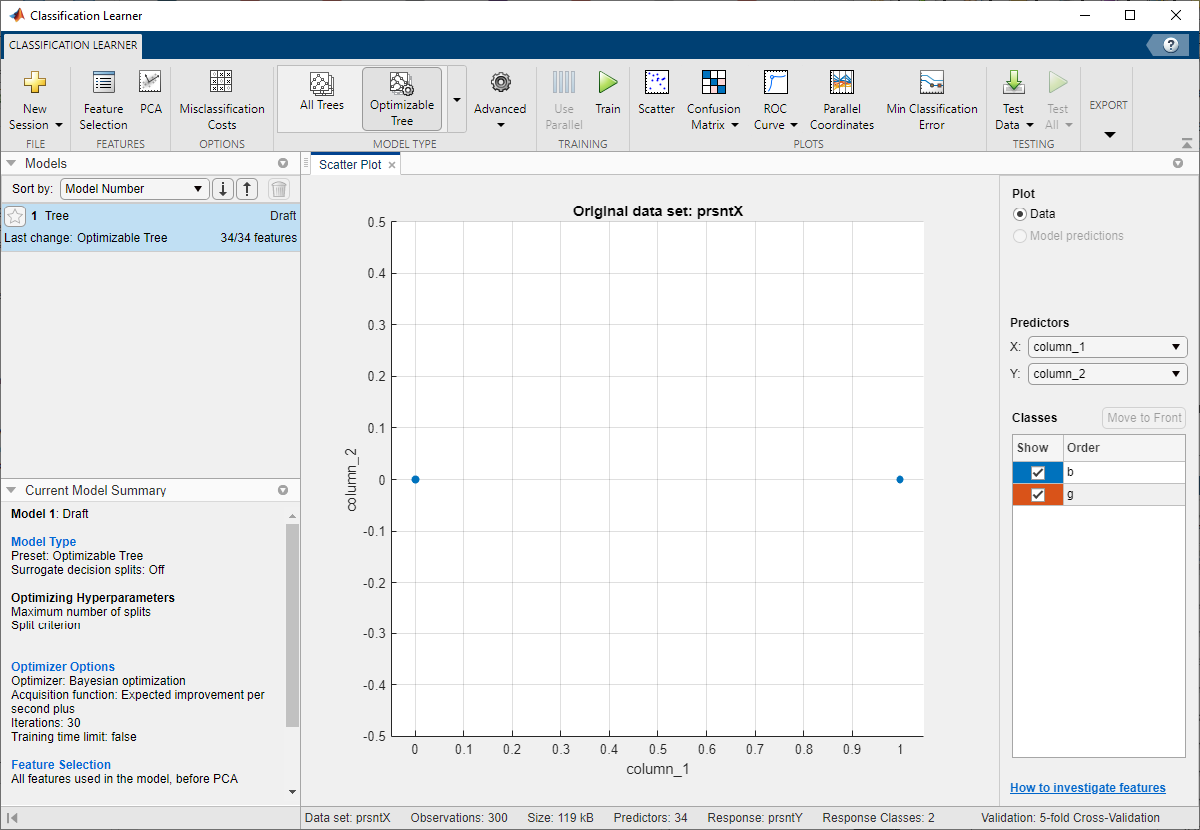

7. In the **Training** section, click **Train**. The app displays a **Minimum Classification Error Plot** as it runs the optimization process. At each iteration, the app tries a different combination of hyperparameter values and updates the plot with the minimum validation classification error observed up to that iteration, indicated in dark blue. When the app completes the optimization process, it selects the set of optimized hyperparameters, indicated by a red square. For more information, see [Minimum Classification Error Plot](docid:stats_ug#mw_10fc128a-9d9b-4531-9c1d-f945fd9cfcd2).

The app lists the optimized hyperparameters in both the **Optimization Results** section to the right of the plot and the **Optimized Hyperparameters** section of the **Current Model Summary** pane. In general, the optimization results are not reproducible.

8. Export the model to the MATLAB workspace. On the **Classification Learner** tab, in the **Export** section, click **Export Model** and select **Export Model**, then click **OK**. The default name for the exported model is `trainedModel`. 

Alternatively, you can generate MATLAB code that trains a classification model with the same settings used to train the model in the app. On the **Classification Learner** tab, in the **Export** section, click **Generate Function**. The app generates code from your session and displays the file in the MATLAB Editor. The file defines a function that accepts predictor and response variables, trains a classification model, and performs cross-validation. Change the function name to `trainClassificationTreeModel` and save the function file. Train a decision tree classification model by using the `trainClassificationTreeModel` function.

trainedModel = trainClassificationTreeModel(prsntX,prsntY);

9. Extract the trained model from the `trainedModel` variable. `trainedModel` contains a [`ClassificationTree`](docid:stats_ug#bstpa6f-1) model object in the `ClassificationTree` field.

treeMdl = trainedModel.ClassificationTree;

Because hyperparameter optimization can lead to an overfitted model, the recommended approach is to create a separate test set before importing your data into the Classification Learner app and see how the optimized model performs on your test set. For more details, see [Train Classifier Using Hyperparameter Optimization in Classification Learner App](docid:stats_ug#mw_dd7338f0-9866-449d-84a6-5e6210f8ff3d).

## Create Simulink Model

This example provides the Simulink model `slexIonosphereClassificationTreePredictExample.slx`, which includes the [ClassificationTree Predict](docid:stats_ug#mw_d5dfffe4-12bb-4a68-ab65-00b4f321f2c5) block. You can open the Simulink model or create a new model as described in this section.

Open the Simulink model `slexIonosphereClassificationTreePredictExample.slx`.

SimMdlName = 'slexIonosphereClassificationTreePredictExample'; 
open_system(SimMdlName)

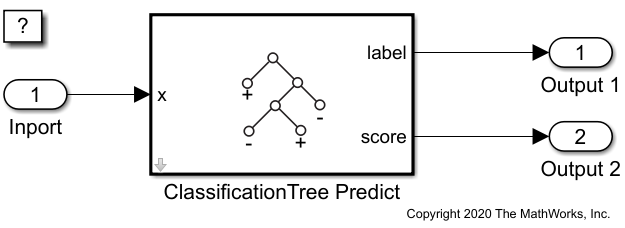

The `PreLoadFcn` callback function of `slexIonosphereClassificationTreePredictExample` includes code to load the sample data, train the model, and create an input signal for the Simulink model. If you open the Simulink model, then the software runs the code in `PreLoadFcn` before loading the Simulink model. To view the callback function, in the **Setup** section on the **Modeling** tab, click **Model Settings** and select **Model Properties**. Then, on the **Callbacks** tab, select the `PreLoadFcn` callback function in the **Model callbacks** pane.

To create a new Simulink model, open the **Blank Model** template and add the ClassificationTree Predict block. Add the Inport and Outport blocks and connect them to the ClassificationTree Predict block.

Double-click the ClassificationTree Predict block to open the Block Parameters dialog box. You can specify the name of a workspace variable that contains the trained model. The default variable name is `treeMdl`. Click the **Refresh** button. The dialog box displays the options used to train the model `treeMdl` under **Trained Machine Learning Model**. Select the **Add output port for predicted class scores** check box to add the second output port **score**.

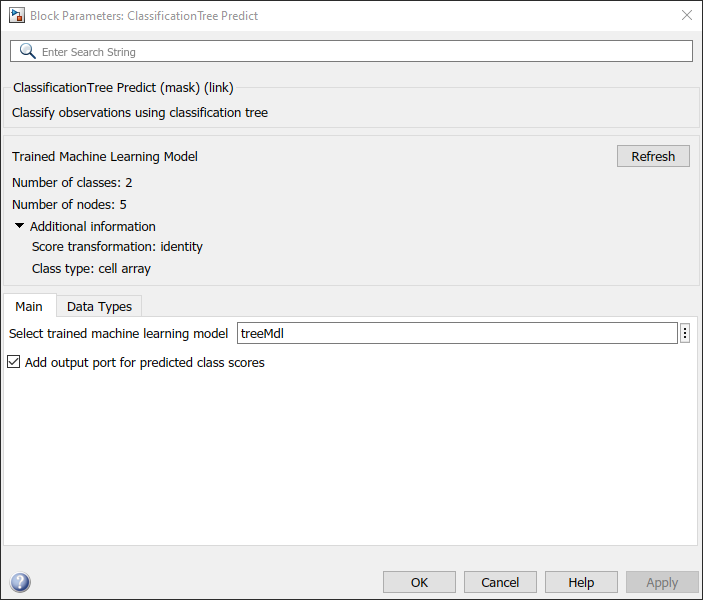

The ClassificationTree Predict block expects an observation containing 34 predictor values. Double-click the Inport block, and set the **Port dimensions** to 34 on the **Signal Attributes** tab.

Create an input signal in the form of a structure array for the Simulink model. The structure array must contain these fields:

- `time` — The points in time at which the observations enter the model. In this example, the duration includes the integers from 0 through 50. The orientation must correspond to the observations in the predictor data. So, in this case, `time` must be a column vector.

- `signals` — A 1-by-1 structure array describing the input data and containing the fields `values` and `dimensions`, where `values` is a matrix of predictor data, and `dimensions` is the number of predictor variables.

 Create an appropriate structure array for future radar returns.

radarReturnInput.time = (0:50)';
radarReturnInput.signals(1).values = ftrX;
radarReturnInput.signals(1).dimensions = size(ftrX,2);

To import signal data from the workspace: 

- Open the Configuration Parameters dialog box. On the **Modeling** tab, click **Model Settings**.

- In the **Data Import/Export** pane, select the **Input** check box and enter `radarReturnInput` in the adjacent text box. 

- In the **Solver** pane, under **Simulation time**, set **Stop time** to `radarReturnInput.time(end)`. Under **Solver selection**, set **Type** to `Fixed-step`, and set **Solver** to `discrete (no continuous states)`.

For more details, see [Load Signal Data for Simulation](docid:simulink_doccenter#import-data).

Simulate the model.

sim(SimMdlName);

When the Inport block detects an observation, it directs the observation into the ClassificationTree Predict block. You can use the [Simulation Data Inspector](docid:simulink_ref#mw_df415982-8312-413a-8c53-28d643c76e75) to view the logged data of the Outport blocks.

*Copyright 2020 The MathWorks, Inc.*